# Tuning ottimale controllore PID - joint1

### Caricamento modelli dei processi

clear all; clc; close all

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

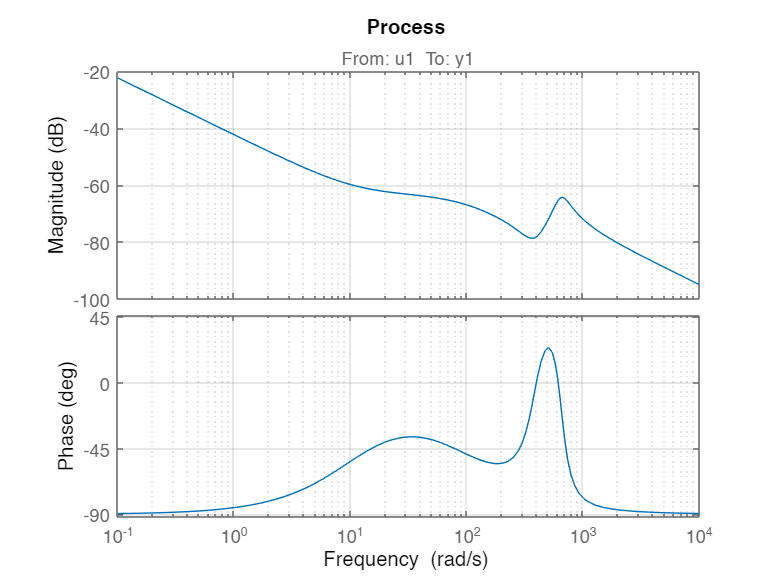

load modello_j1.mat

process = modello_continuo_tf_j1;
figure
bodeplot(process)
grid on; title('Process');

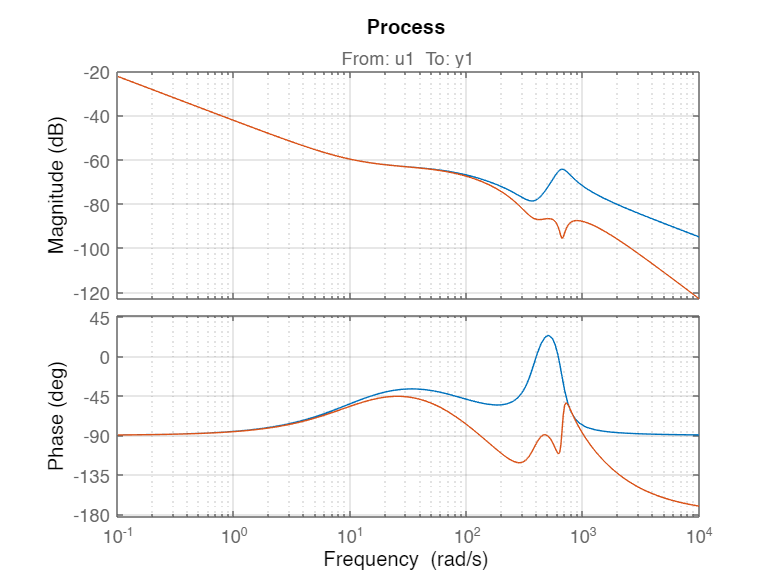

s=tf('s');
[gpeak,fpeak] = getPeakGain(process*10^(70/20),[],[300 1000]); % constraint of the frequencies personalize for our system
if(gpeak > 1/10)
    notch_filter=notch(fpeak,1/10/gpeak);
else
    notch_filter=1;
end
process_notch = process * notch_filter;
w_f=400;
filter = 1/(s/w_f+1)^1;

figure
bode(process,process_notch*filter)
grid on; title('Process');

% ylim([-120 -40])
total_process = minreal(process_notch * filter);

tot_filter = filter * notch_filter;


Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

#### Inner loop: output Filtered **P **


$$C_2(s)=K_p \cdot \frac{1}{T_{fu}s+1}$$


Cifra di merito da minimizzare:


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 250;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x, 0, 0, 0, 0],total_process,internal_joint1.wc_des,0);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
internal_joint1.MS = 1.5;

% Reiezione disturbo di misura
internal_joint1.wh = 2000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 10;
internal_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 65;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints([x, 0, 0, 0, 0], total_process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dl_max, internal_joint1.PM_min,0);

### Ottimizzatore interno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
internal_joint1.aKp = [5800, 100, 10000];
%internal_joint2.aKi = [0, 0, 0];
%internal_joint2.aKd = [0, 0, 0];
%internal_joint2.aTfd = [0, 0, 0];
%internal_joint2.aTfu = [1/300, 1/500, 1/40];

x0 = [internal_joint1.aKp(1)];


problem = createOptimProblem('fmincon','x0',x0,  'objective',J, 'lb',[internal_joint1.aKp(2)],  'ub', [internal_joint1.aKp(3)],  'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       27         876                                     876            1    Initial Point
     200     1252         876                                     876            1    Stage 1 Local
     266     1349         876          1386         1515          876            1    Stage 2 Local
     300     1383         876     2.208e+04         1663                              Stage 2 Search
     400     1483         876          1310         1310                              Stage 2 Search
     500     1583         876     1.686e+04         1515                              Stage 2 Search
     537     1644         876          2159         2182          876            1    Stage 2 Local
     538     1669         876          2123         2159          876            1    Stage 2 Loc

x = 6.3471e+03

nlcon(x)

ans =    -0.0132   -0.0998   -0.3337   -0.0000


s=tf('s');
Kp = x(1);
Cv_joint1 = tf(Kp);
Cv_joint1.InputName = 'sp-vel';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = total_process*Cv_joint1;

figure;
subplot(1,2,1)
margin(Loop_int_joint1)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint1))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint1))

ans = 1.1689

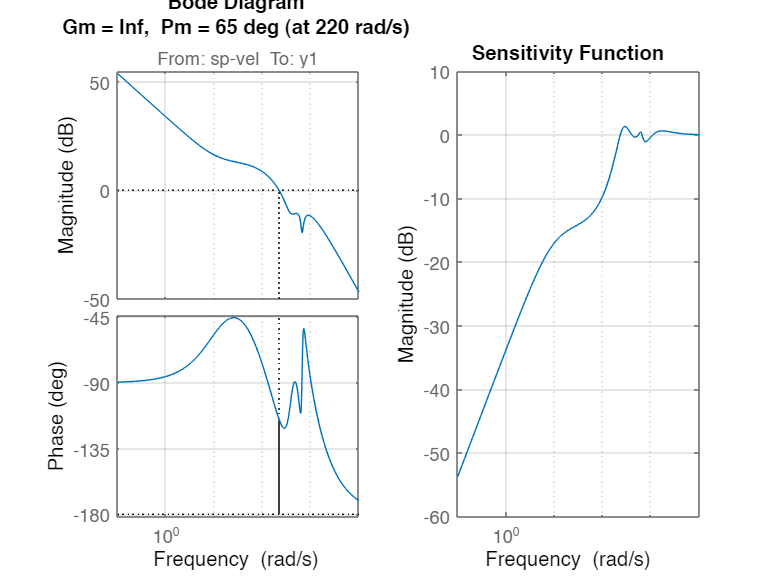

grid on

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\textrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


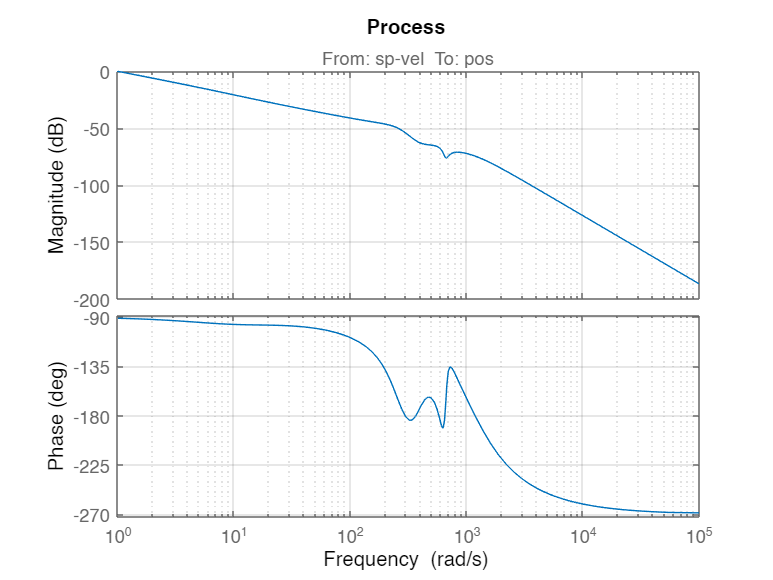

process_ext = minreal(feedback(Loop_int_joint1,1)*1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';
figure
bodeplot(process_ext)
grid on; title('Process');

external_joint1.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function([x(1), x(2), 0, 0, 0],process_ext,external_joint1.wc_des,0);

### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint1.MS = 1.5;

% Reiezione disturbo di misura
external_joint1.wh = 2000;
external_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint1.wl = 10;
external_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint1.PM_min = 75;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint1.wl;external_joint1.wh]));

nlcon = @(x)pid_filt_constraints([x(1), x(2), 0, 0, 0], process_ext, w_vector, ...
                                 external_joint1.MS, external_joint1.wh, external_joint1.Fh_max, ...
                                 external_joint1.wl, external_joint1.Dl_max, external_joint1.PM_min,0);

### Ottimizzatore esterno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint1.aKp = [130, 0.01, 2000];
external_joint1.aKi = [1/200, 1/1000, 100];
%external_joint2.aKd = [0, 0, 0];
%external_joint2.aTfd = [0, 0, 0];
%external_joint2.aTfu = [0, 0, 0];


x0 = [external_joint1.aKp(1), external_joint1.aKi(1)];


opt1=optimoptions("ga","MaxTime",3600*0.1,'InitialPopulation',x0,'Display','iter');

x1=ga(J,2,[],[],[],[],[external_joint1.aKp(2), external_joint1.aKi(2)] ...
    ,[external_joint1.aKp(3), external_joint1.aKi(3)] ...
    ,nlcon,opt1);


Single objective optimization:
2 Variable(s)
4 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2524       14419.1    3.153e-06      0
    2           4986       14418.9    0.0001163      0
    3           6085       14508.9            0      0
Optimization terminated: time limit exceeded.



nlcon(x1)

ans =    -0.0964   -0.0891   -0.0674   -0.0653


s=tf('s');
Kp=x1(1); Ki=x1(2);
Cp_joint1=(Kp+Ki/s);
Cp_joint1.InputName = 'sp-vel';
Cp_joint1.OutputName = 'pos';

Loop_ext_joint1 = process_ext*Cp_joint1;

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure;
subplot(1,2,1)
margin(Loop_ext_joint1)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_ext_joint1))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_ext_joint1))

ans = 1.4326

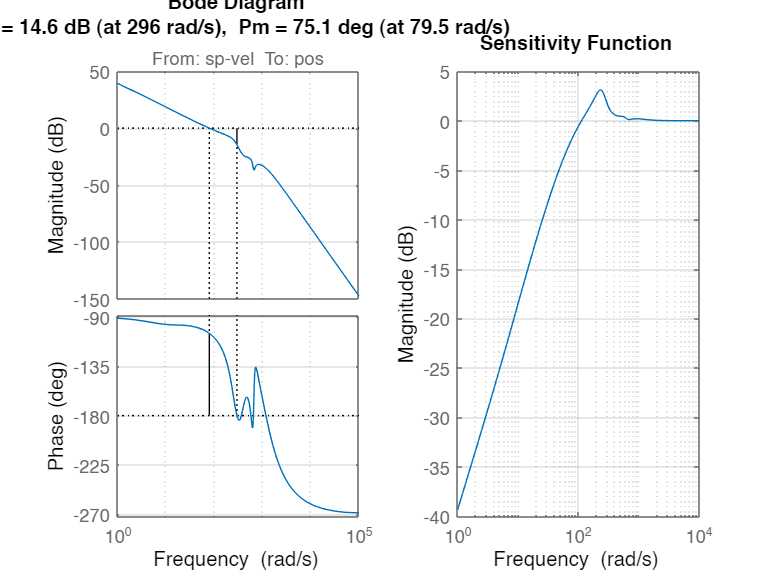

grid on


x = [x, 0, 0, 0, 0];
x1 = [x1, 0, 0, 0];
save("parameters_controller_int_joint1_" +num2str(w_f)+"_"+num2str(internal_joint1.PM_min)+".mat", "x")
save("parameters_controller_ext_joint1_"+num2str(w_f)+"_"+num2str(external_joint1.PM_min)+".mat","x1")
save("tot_filter_joint1_"+num2str(w_f)+"_"+num2str(external_joint1.PM_min)+".mat","tot_filter");